## **Lab 1 Part 2 Matlab for Multiclass Classification**

### 2.1 Introduction 

- The objective of this task is to learn about designing and implementing basic machine learning algorithms for classification, with a focus on methods that are extensible to deep learning.

- A key aim, as for the part on regression, is to see how the machine learning is implemented as basic maths in code and then do the equivalent task using the Deep Learning Toolbox - this should give you valuable insight into how the toolbox works.

- You will need the Deep Learning Toolbox installed.

- This lab is not assessed.

- For related background reading to this lab, you can check the Lecture 2 notes/slides on Blackboard and [Chapter 5](https://www.deeplearningbook.org/contents/ml.html) of the book Deep Learning (Goodfellow, Bengio and Courville, 2016).

- Work through all lab tasks first, then do the quiz on Blackboard.

### 2.2 Define data and pre-process

The classification methods are applied to the Fisher-Iris data set here.

The Fisher Iris data set is a classic machine learning data set for multiclass classification that is focused on classifying the type of species of Iris flower.

The data set consists of 50 samples from each of three species of Iris (Iris setosa, Iris virginica and Iris versicolor). Four features were measured from each sample: the length and the width of the sepals and petals, in centimeters.

Therefore, there are 3 classes and 4 input features** but we will only use 2 input features** for easier visualisation of the results. 

clear all

%% data loading and pre-processing
 
% initialise the random number generator seed for repeatable results
rng(1,'twister');
 
% load simple data set - Fisher Iris
load fisheriris
 
% extract raw input data (features)
m = size(meas,1);      % number of data samples
x1raw = meas(1:m,1);   % feature 1
x2raw = meas(1:m,2);   % feature 2

Now we need to one-hot encode the class labels for use in training a softmax model

% one-hot encode class labels (i.e. the output data)
targets = categorical(species);  % define class labels as integers
Y = (onehotencode(targets,2))';  % one encode targets
K = size(Y,1);                   % number of classes

Standardise the data - it is often important to standardise the input data because large differences in scaling between input features can badly affect the learning process. We usually standardise by setting each input feature to zero-mean and scale to a standard deviation of one.

% standardise features - zero mean and set std to one
x1 = (x1raw-mean(x1raw))./std(x1raw);
x2 = (x2raw-mean(x2raw))./std(x2raw);

Now we can create the input feature matrix from x1 and x2 and a bias (offset term of 1) and also split the data into training and vaidation data sets:

% create feature matrix
X = [ones(1,m); x1'; x2']; % input/feature matrix with bias term
n = size(X,1);             % number of features + bias

% create training, validation and test indices
r = randi([1 m],1,m);         % set of random indices
trainIdx = r(1:70);           % training data indices
valIdx = r(71:100);           % validation data indices
testIdx = r(101:150);         % test data indices
ntrain = length(trainIdx);    % number of training data samples
nval = length(valIdx);        % number of validation data samples

### 2.3 Machine learning - train a linear multiclass classifier using SGD 

The model we are trying to identify from data pairs $\left(x,y\right)$ is a linear model of the form ${\theta_i }^{\;T} x$ passed through a softmax function ,which normalises the linear model output to the range 0-1,


$$\hat{y_i \;} =p\left(Y=i|x;\theta \;\right)=\frac{\exp \left({\theta_i }^{\;T} x\right)}{\sum_k \;\exp \left(\theta_{\;k}^{\;T} \;x\right)\;}\;\;i=0,\ldots,K-1$$


i.e. the model output is $\hat{y}$, $\theta_{i\;} \;$are the parameters for model $i$ - there is a separate model $i$ to predict each class - and the parameters $\theta_{i\;} \;$are unknown. We will use stochastic gradient descent to estimate the model parameters. 

The loss function here is the categorical cross-entropy loss (equivalent to the negative log-likelihood in maximum likelihood estimation for the case of a categorical distribution of data) 


$$J\left(\theta \;\right)=-\sum_{j=1} \sum_{k=1} y_{j,k} \;\log \left({\hat{y\;} }_{j,k} \right)\;\;$$


The SGD update is


$$\theta \gets \theta -\epsilon \;g$$


where $\epsilon$ is the SGD learning rate and $g$ is the estimate of the loss function gradient. 

Note, in the code below, all the data is presented one at a time to the learning update rule, a minibatch size of 1, and the code loops through all the data once only - an epoch size of 1. Make sure you understand the distinction between a training iteration and a training epoch.

The SGD code for parameter estimation is below (this takes about 30 seconds to run):

%% run parameter estimation using SGD

% initialise SGD algorithm
theta = 0.01*rand(K,n); % initialise parameters
epsilon = 0.1;          % learning rate
maxIter = ntrain;       % number of training iterations

% estimate model parameters using SGD
for j = 1:maxIter
    
    % calculate loss gradient for each class function
    g = [];
    for k = 1:K
        
        % extract class label for current iteration
        y = Y(k,r(j));
        
        % softmax prediction (probability of class k)
        yhat = exp(theta(k,:)*X(:,r(j)))./sum(exp(theta*X(:,r(j))));

        % estimate loss function gradient from single data point
        g(k,:) = (yhat - y)*X(:,r(j))';
        
    end

    % SGD update rule
    theta = theta - epsilon*g;
 
    % store parameter values
    thetaStore(j).theta = theta;
end


### 2.4 Plot the output and evaluate results

Let's plot the output from the SGD learning algorithm to visualise and understand better what is going on - note that plotting the output is more complicated and longer than doing the actual machine learning. You will NOT be examined on plotting output!!

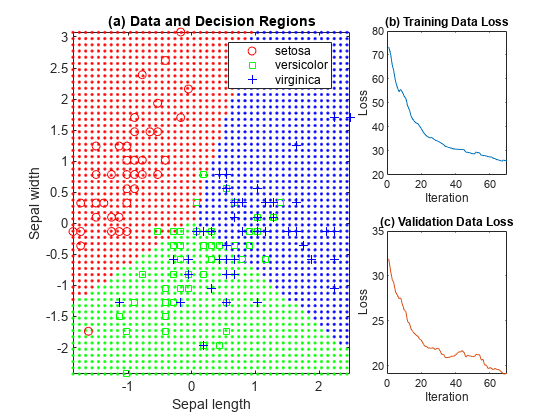

%% plot classifier output

% setup figure for plotting
h1 = figure;
cols = get(0, 'DefaultAxesColorOrder'); % define colours for plotting
 
% setup grid of data points for finding classifier decision regions
x1range = min(x1):.1:max(x1); % data range for feature 1
x2range = min(x2):.1:max(x2); % data range for feature 2
[xx1, xx2] = meshgrid(x1range,x2range); % grid of feature data
XGrid = [ones(1,length(xx1(:))); xx1(:)'; xx2(:)']; % matrix of feature data
 
% plot results: loop over stored data
for j = 1:maxIter
    
    % unpack parameter values
    theta = thetaStore(j).theta;
    
    % training data: softmax class prediction
    Yhat = exp(theta*X(:,trainIdx))./sum(exp(theta*X(:,trainIdx)));
    
    % training data: loss function evaluation
    lossTrain(j) = -sum(sum(Y(:,trainIdx).*log(Yhat)));
    
    % loss function evaluation on validation data
    Yhat = exp(theta*X(:,valIdx))./sum(exp(theta*X(:,valIdx)));
    
    % validation data: loss function evaluation
    lossVal(j) = -sum(sum(Y(:,valIdx).*log(Yhat)));
    
    % find classifier decision regions
    YGrid = exp(theta*XGrid)./sum(exp(theta*XGrid));  % class probabilities
    [~,classPrediction] = max(YGrid);                 % class predictions
    
    % plot classifier decision regions and data
    figure(h1);
    subplot(2,3,[1 2 4 5]); cla
    gscatter(xx1(:), xx2(:), classPrediction,'rgb'); hold on
    gscatter(x1, x2, targets,'rgb','os+');
    xlim([min(x1) max(x1)]); ylim([min(x2) max(x2)]);
    xlabel('Sepal length');
    ylabel('Sepal width');
    title('(a) Data and Decision Regions');
    
    % plot training loss function
    subplot(2,3,3); cla;
    plot(lossTrain,'color',cols(1,:));
    title('(b) Training Data Loss');
    xlabel('Iteration');
    ylabel('Loss')
    
    % plot validation loss function
    subplot(2,3,6); cla;
    plot(lossVal,'color',cols(2,:))
    title('(c) Validation Data Loss');
    xlabel('Iteration');
    ylabel('Loss')
    drawnow;
end

Note that panel (a) in the figure shows the three classes of flower species by colour (red, green and blue) as a function of the two input features. It is reasonably clear from this visualisation that the classifier is learning linear decision boundaries, because it is based on a linear model. Of course once you move to a higher dimensional input space (>2) you cannot make these nice visualisations. 

We monitor the value of the loss on both the training and validation data. The reason for monitoring loss on separate validation data is that this is a better test of the generalisation ability of the model than just examining the performance on training data (to which the model can overfit).

Finally, let's plot a confusion matrix, which is the tool most commonly used to analyse classification results (it is a table of true outputs versus model predictions):

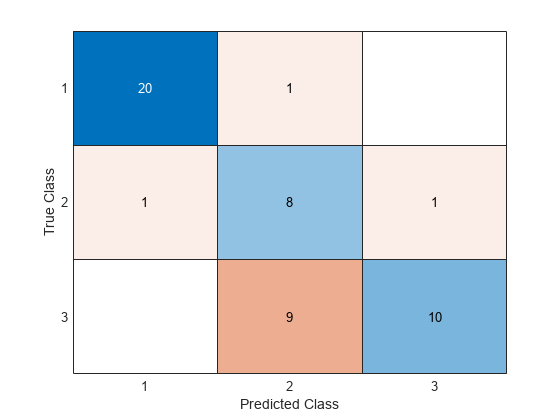

%% evaluate model on test data
 
% class probabilities
Yhat = exp(theta*X(:,testIdx))./sum(exp(theta*X(:,testIdx))); 

% convert class labels to integer values
target_integers = grp2idx(species(1:m)); % convert species labels to integers 

% class predictions
[~,classPrediction] = max(Yhat);
 
% calculate confusion matrix
cm = confusionmat(target_integers(testIdx),classPrediction');         
 
% plot confusion matrix
figure;
confusionchart(cm) 

### 2.5 Deep Learning Toolbox for Classification

We can do the same task as above but using the Deep Learnin Toolbox instead. The advantage of using the toolbox is that it is more easily extended to complex tasks. But note, in this example it uses the same underlying methods that we developed above.

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       60.00% |       69.33% |       1.0632 |       0.8646 |          0.0100 |
|       4 |          50 |       00:00:04 |      100.00% |       70.67% |       0.4975 |       0.7795 |          0.0100 |
|       7 |         100 |       00:00:05 |      100.00% |       77.33% |       0.3341 |       0.7255 |          0.0100 |
|      10 |         150 |       00:00:05 |       80.00% |       77.33% |       0.6613 |       0.6886 |          0.0100 |
|      1

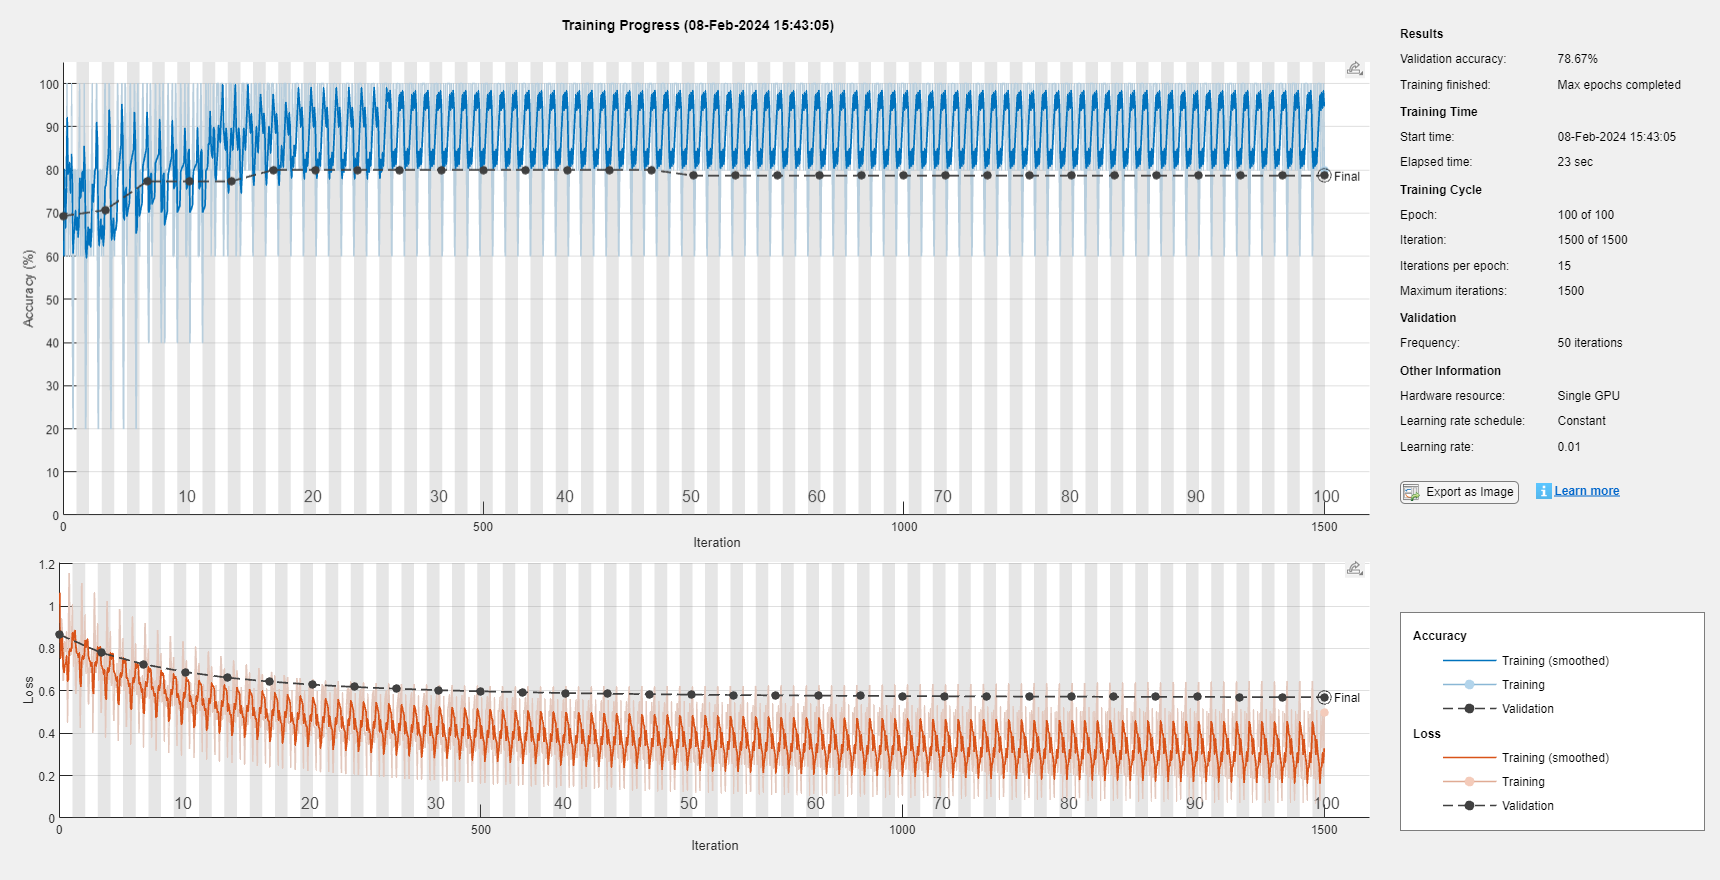

%% pre-process data - similar but slightly different to above

% pre-preprocess Fisher Iris data
Y = targets;                           % define output data as categorical labels - as above
X_scaled = [x1 x2];                    % input data - as above
num_features = size(X_scaled,2);       % number of features
num_classes = length(unique(species)); % number of classes
m = size(X_scaled,1);                  % number of data samples

% create randomised training and validation data - as above
X_train = X_scaled(r(1:m/2),:);
X_val = X_scaled(r(m/2+1:m),:);
Y_train = Y(r(1:m/2),:);
Y_val = Y(r(m/2+1:m),:);

% define the deep feedforward network layers
layers = [featureInputLayer(num_features)
    fullyConnectedLayer(num_classes)
    softmaxLayer
    classificationLayer];

% analyze the network
analyzeNetwork(layers)

%% Train network
% Specify the training options
options = trainingOptions("sgdm", ...
    "MiniBatchSize",20, ...
    "MaxEpochs",100, ...
    "InitialLearnRate",0.01, ...
    "ValidationData",{X_val,Y_val}, ...
    "Verbose",true, ...
    "Plots","training-progress", ...
    "Momentum",0);

% Train the network using the training data
net = trainNetwork(X_train,Y_train,layers,options);


%% evaluate model on test data

% Classify the validation images using the trained network
[YPred,probs] = classify(net,X_val);
accuracy = 100*mean(YPred == Y_val); % accuracy
disp(["Validation Accuracy: " num2str(accuracy) "%"]);

    "Validation Accuracy: "    "78.6667"    "%"



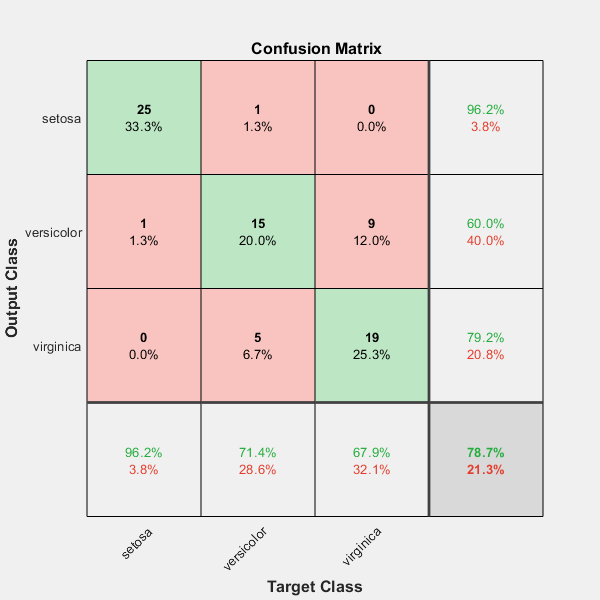

% plot confusion matrix
figure;
plotconfusion(Y_val,YPred)

Hopefully you now see how easy it is to do either manual coding of the learning algorithm or to use the toolbox. And also you should now appreciate what the deep learning toolbox is doing when you setup the model and call functions like **trainNetwork**.

% End of Lab Task - move onto next task